# Resonant Circuits

1 May 21, B.R.

## Prerequisites: 

We'll use these simple Matlab functions to compute capacitive and inductive reactances. Save them individually in your PATH if you haven't done so already. 

%{
function zc = zc(farad, hz)
% function zc = zc(farad, hz)
% compute complex impedances of capacitor farad at frequencies hz
% hz can be a vector or matrix, and is persistent

% 7 apr 21 BR

persistent hzz
if nargin == 2, hzz = hz; end
zc = 1 ./ (1j*2*pi*farad*hzz);
end

% ========================================

function zl = zl(henry, hz)
% function zl = zl(henry, hz)
% compute complex impedances of inductor henry at frequencies hz
% hz can be a vector or matrix, and is persistent

persistent hzz
if nargin == 2, hzz = hz; end
zl = 1j*2*pi*henry*hzz;
end

% ========================================

function zparallel = zp(z1, z2)
% function zparallel = zp(z1, z2)
% returns z1 .* z2 ./ (z1 + z2), the parallel impedance
 
zparallel = z1 .* z2 ./ (z1 + z2); 
end
%}

## What is resonance? 

Ask Wikipedia ([https://en.wikipedia.org/wiki/Resonance](https://en.wikipedia.org/wiki/Resonance))  

- "Resonance describes the phenomenon of increased amplitude that occurs when the frequency of a periodically applied force (or a Fourier component of it) is equal or close to a natural frequency of the system on which it acts. When an oscillating force is applied at a resonant frequency of a dynamical system, the system will oscillate at a higher amplitude than when the same force is applied at other, non-resonant frequencies.[3]"

There are many concepts here. A dynamical system is ... something with "internal degrees of freedom". A characteristic of such a system is one (or more) natural frequencies -- one way to think of those are the frequencies that energy naturally sloshes back and forth, consistent with the "boundary conditions" of the system. I'm probably adding more new concepts than explaining the previous ones ... 

Simplest example we're all familiar with in our childhood is a swing, a human pendulum. Each time our friends gave us a push (or we extended and pulled in our feet), we'd add kinetic energy to the pendulum. If this was more than lost due to friction, then we'd swing higher and higher with each cycle. The swing has a natural or resonant frequency, roughly given by $f_r = \frac{1}{2\pi}\sqrt{\frac{g}{L}$ ([https://en.wikipedia.org/wiki/Pendulum](https://en.wikipedia.org/wiki/Pendulum)). When a bully shakes the swing really fast $(f>>f_r)$ the energy doesn't transfer into the swing. Little brother or sister who doesn't get out of the way of the swing can get knocked on their butts by the large accumulated energy in the system overcoming their inertia ... 

Let's continue exploring a kids swing in the frequency domain ... not something you probably did as a child. At very low driven frequencies, $f<<fr$, low amplitude forcing the swing makes it move in phase with the force and at the amplitude of the force, but energy isn't efficiently transferred and doesn't accumulate. Another example of this mode is a rocking chair pushed with our feet slowly on the ground. The chair moves slowly in phase with our feet, and stops when our feet stop. A swing keeps going longer because its energy sloshes back and forth (between kinetic anergy and gravitational potential energy) with little loss per cycle. So systems with low dissapation or friction tend to absorb energy and oscillate near their resonant frequencies, and tend to resist energy transfer far from their resonant frequencies. 

That's why we use the metaphor of resonance when talking about ideas, e.g., "socialism resonanted with a student who's family experienced ravages of capitalism, but the wealthy student didn't buy it".  

## Resonance in electronics

Resistors dissapate energy as they oppose ("resist") current flow. But capacitors and inductors store (and release) energy -- because their currents and voltages are out of phase with each other. With an L and C in a circuit (that doesn't have too much R), at a *natural frequency*, electrical energy will slosh back and forth between the L and C, slowly dissapating with each pass through the R. In a pendulum, the energy sloshes between kinetic and gravitational potential energy. What are the analogs in an electric circuit??? Think about it ...  They are the magnetic field energy stored within the inductor and the electric field energy stored within the capacitor. Let's numerically model this circuit using specific values: 

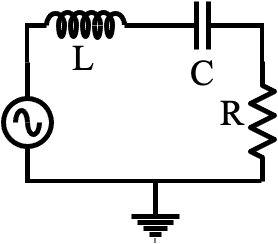

Figure 1. LRC series circuit, also Figure 7.22 in Boysen and Kybett. 

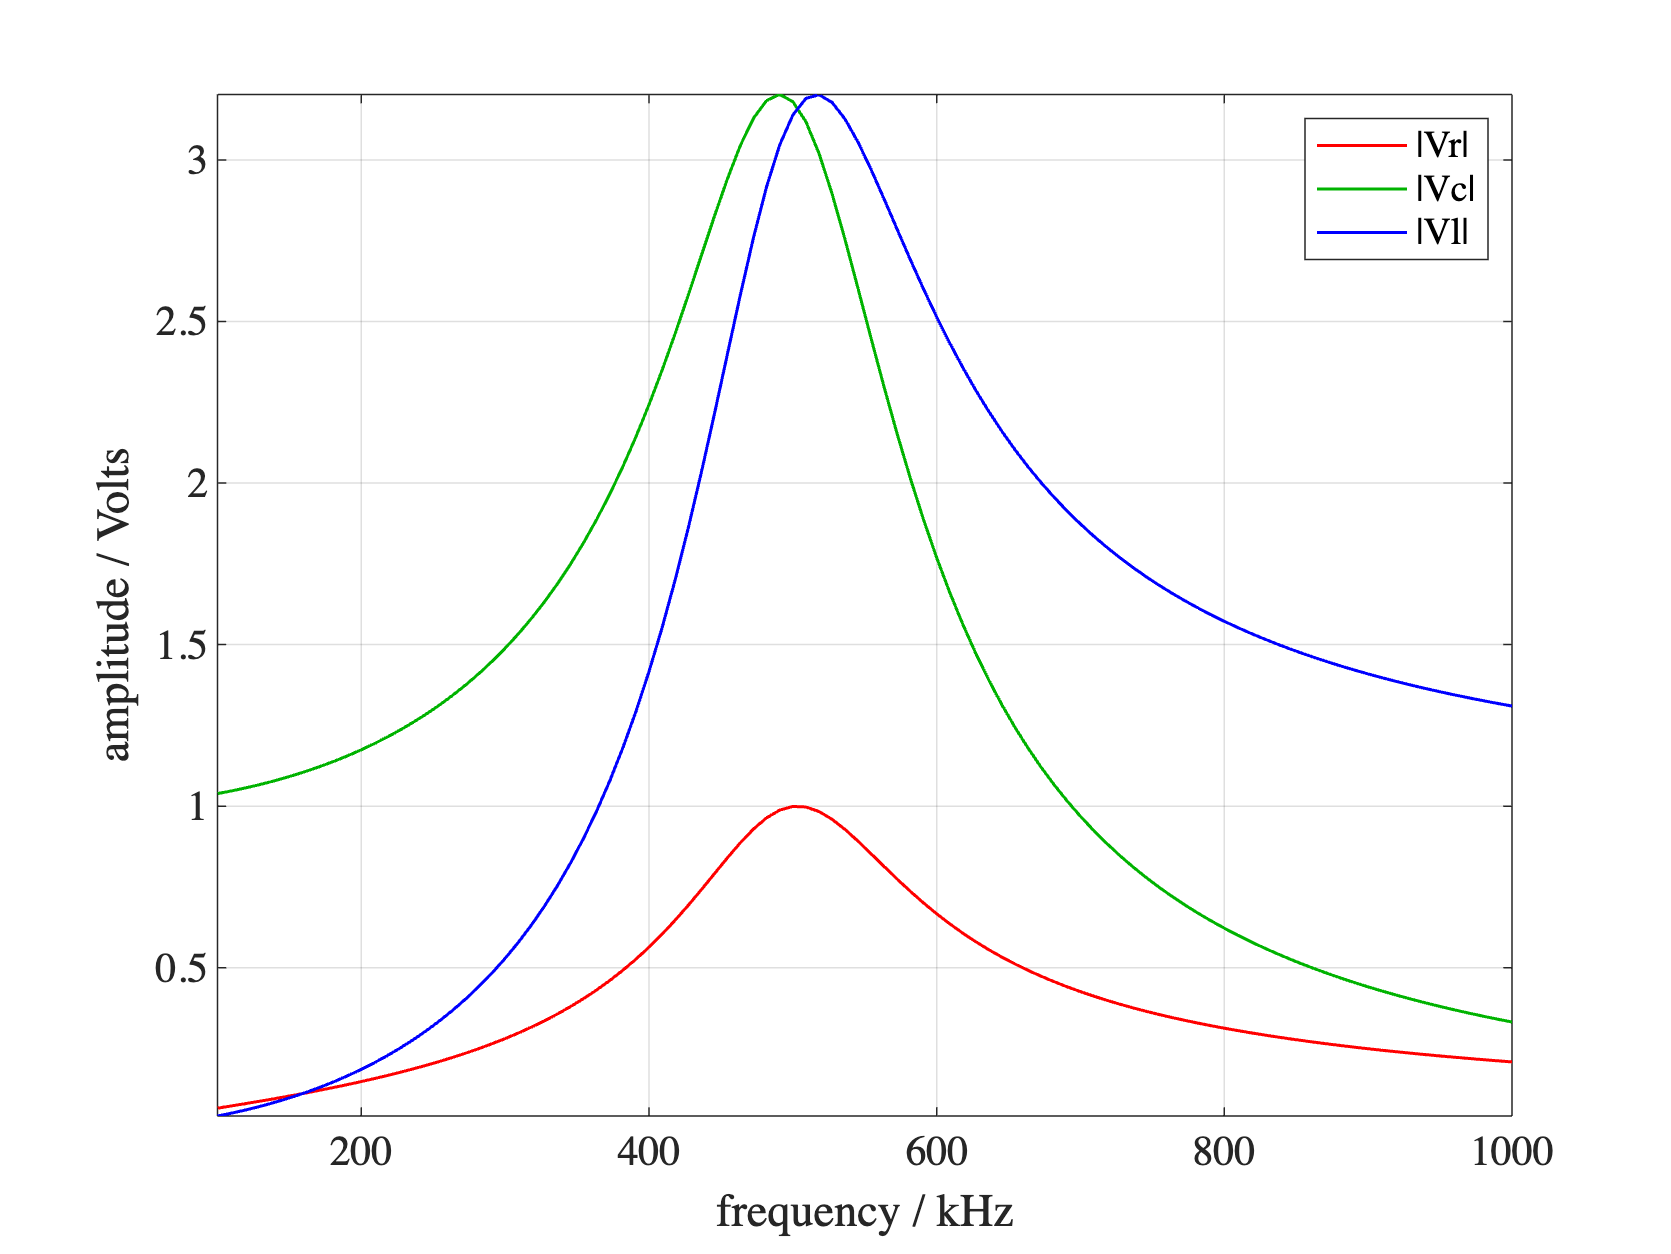

L = 100e-6; % Henry
C = 1e-9; % Farad
R = 100; % Ohms
freqs = linspace(1e5, 1e6)'; % Hz -- using linspace because plotting on linear axis
xc = zc(C,freqs); 
xl = zl(L,freqs);
Vin = 1; % amplitude of Vin, volts
Vr = Vin * R ./ (R+xc+xl); % voltage divider
Vc = Vin * xc ./ (R+xc+xl);
Vl = Vin * xl ./ (R+xc+xl);
plot(freqs/1000, abs([Vr Vc Vl]));
xlabel('frequency / kHz'); 
ylabel('amplitude / Volts')
legend('|Vr|','|Vc|','|Vl|')
grid; axis tight;

Characteristic resonance curves, e.g., Fig. 7.28 in Boysen. We tend to focus on the Vr curve because it's in phase with the current, $i
$ = Vr/R, since R is real. Theory gives the location of the |Vr| (and current) peak, the resonant frequency: 

fr = 1/(2*pi*sqrt(L*C)) % resonant frequency

fr = 5.0329e+05

A second important characteristic is the sharpness or relative width of the curve. This is typically described by a dimensionless quantity called "Q", "Q-factor", or "Quality factor" ([https://en.wikipedia.org/wiki/Q_factor](https://en.wikipedia.org/wiki/Q_factor)), which has a variety of definitions, that remarkably are the same: 


$$Q {\stackrel {\mathrm {def} }{=}}\ {\frac {f_{r}}{\Delta f}}={\frac {\omega _{r}}{\Delta \omega }}$$
  


$${\displaystyle Q\ {\stackrel {\mathrm {def} }{=}}\ 2\pi \times {\frac {\text{energy stored}}{\text{energy dissipated per cycle}}}=2\pi f_{r}\times {\frac {\text{energy stored}}{\text{power loss}}}.\,}%$$


For an RLC series circuit (the formula is the inverse for a parallel circuit),


$${\displaystyle Q={\frac {1}{R}}{\sqrt {\frac {L}{C}}}={\frac {\omega _{0}L}{R}}={\frac {1}{\omega _{0}RC}}}$$


A big caveat in the first definition, Q = (resonant frequency / bandwidth), is where or how is the bandwidth defined? The answer is between where the *power* is attenuated by 1/2. Since power ~ voltage$^2$, bandwidth is defined between the two frequencies in the Vr curve where V = 1/sqrt(2) ~.707. We'll add a line there to the graph later. Numerically, 

Q = sqrt(L/C)/R

Q = 3.1623

bandwidth = fr/Q

bandwidth = 1.5915e+05

## How R affects Q

Let's simulate a couple circuits with less resistance:

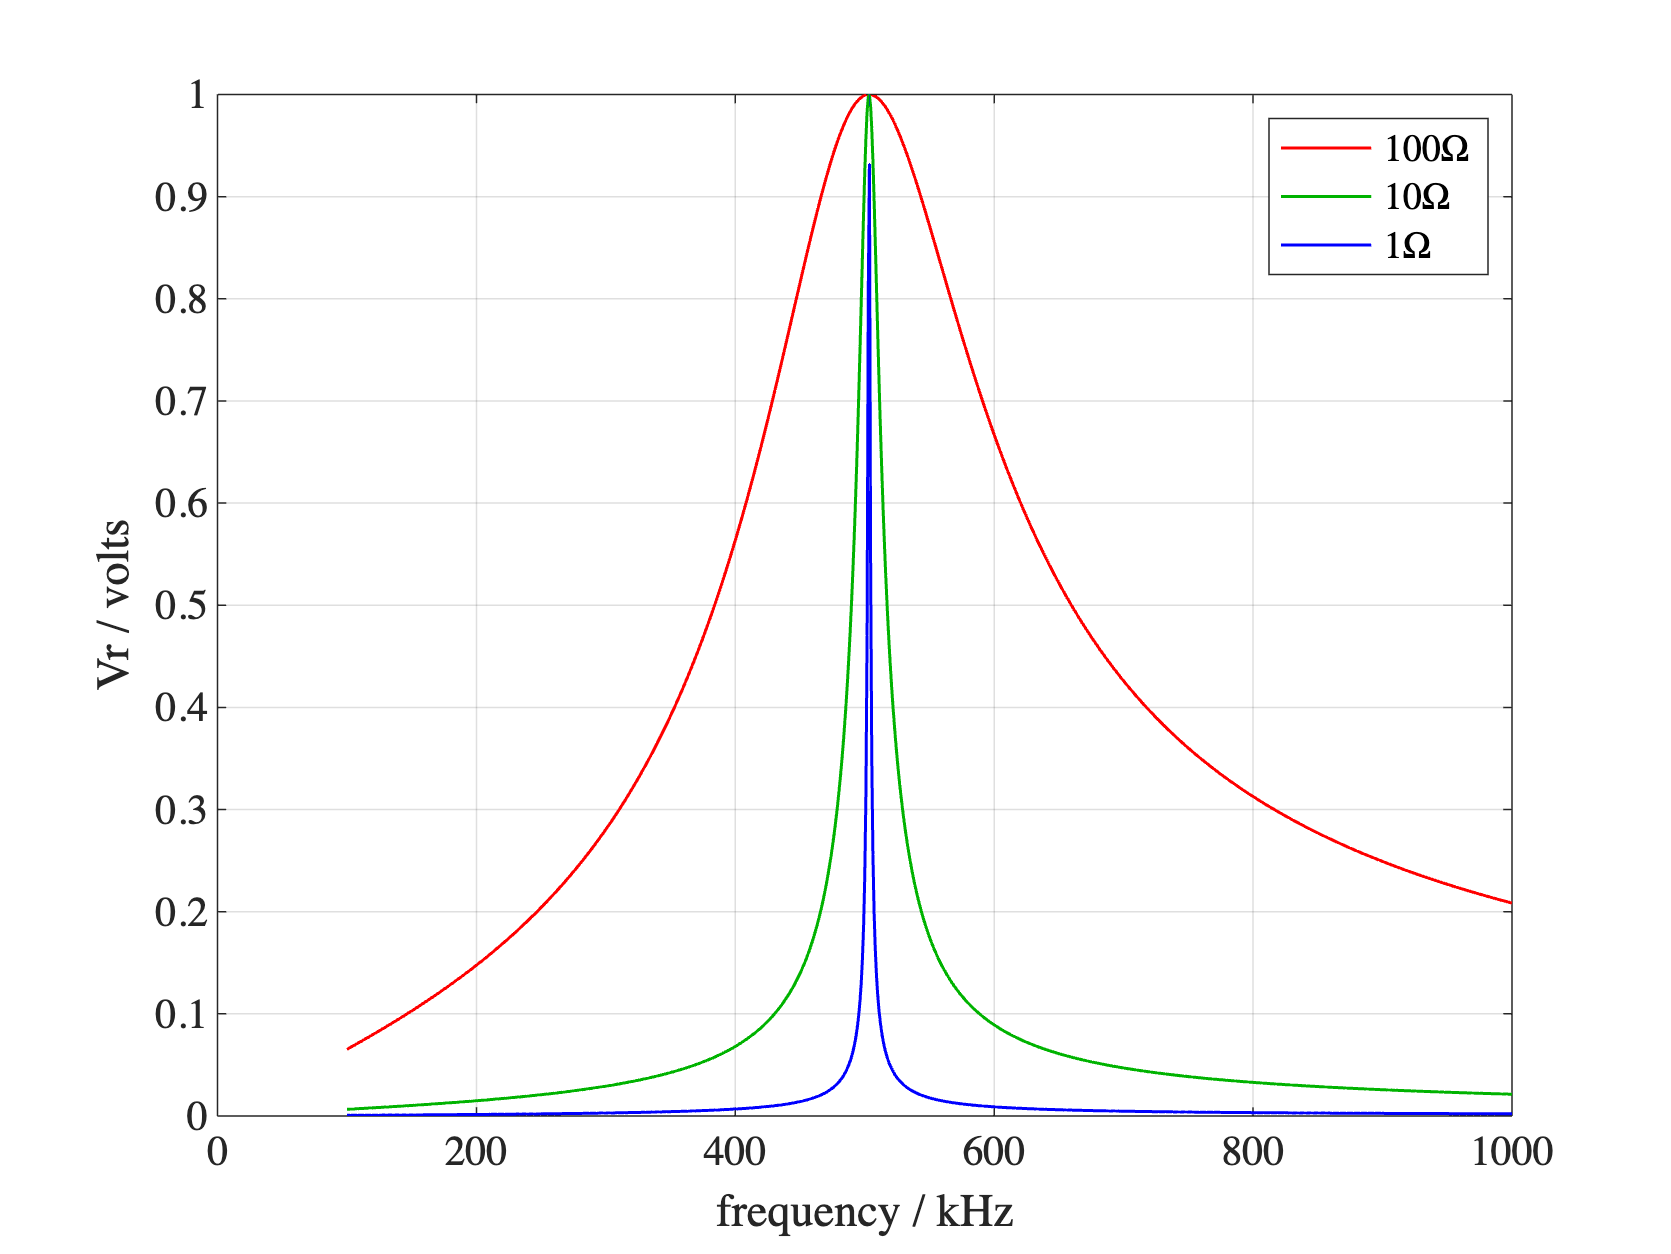

Vr2 = 10 ./(10+xl+xc); % R = 10 ohms
Vr3 = 1 ./(1+xl+xc);  % R = 1 ohm
plot(freqs/1000, abs([Vr Vr2 Vr3]));
legend('100\Omega','10\Omega','1\Omega'); 
xlabel('frequency / kHz'); ylabel('Vr / volts')
grid;

Did you expect the resonant amplitude to decrease with smaller resistance? At resonance with 100$\Omega$, the full Vin is across R. Why would *less* dissapation reduce the voltage on R? A real (physical) inductor has some parasitic series resistance, so if this were empirical measured data, it wouldn't surprise me to see a voltage drop due to $R_{Thevenin}$ or other series parasitic R's. But this *model* should be immune to parasitic R's ... A clue is the asymmetric shape of the green curve. Might we be *undersampling* the peak with our discrete frequency vector? Lets try 1000 frequencies instead of `linspace`'s default 100: 

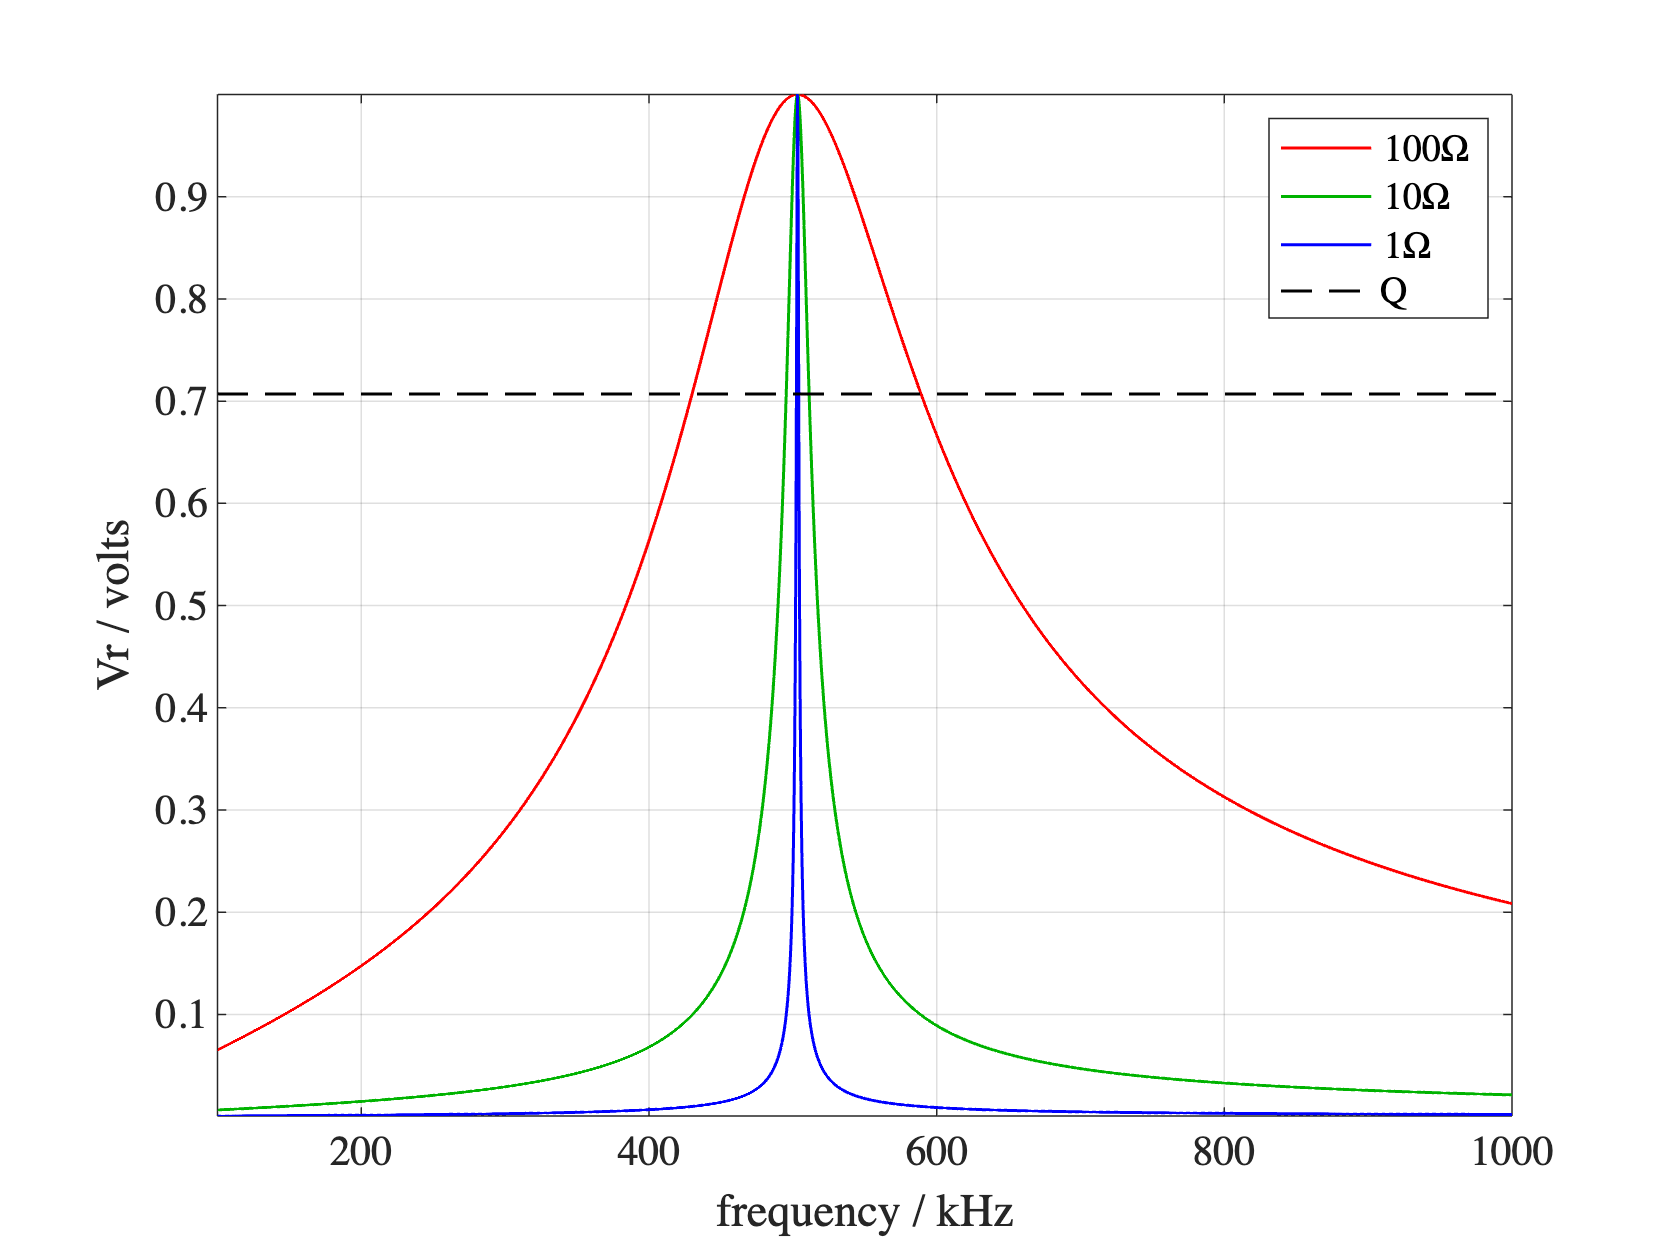

freqs = linspace(1e5, 1e6, 1000)'; % Hz
xc = zc(C,freqs); 
xl = zl(L,freqs);
Vr = Vin * R ./ (R+xc+xl); % voltage divider
Vr2 = 10 ./ (10+xc+xl);
Vr3 = 1 ./ (1+xc+xl);
clf;
plot(freqs/1000, abs([Vr Vr2 Vr3]))
hold on; plot([100 1000],[1 1]/sqrt(2),'--k'); hold off;
axis tight;
legend('100\Omega','10\Omega','1\Omega','Q');
xlabel('frequency / kHz'); ylabel('Vr / volts')
grid;

Everything is the same except more discrete frequency points -- still not enough points apparently to hit the narrow resonance peak with $1\Omega$ (Q = 316), but clearly undersampling was the problem. If you don't believe, rerun the code with 2000 frequencies. All these resonance curves have the same amplitude, but the sharper they are, the closer together the frequencies needed to sample (calculate) the peak. In any experiment, how many data points do you need? Enough to reveal the characteristics underlying the data ... and that depends on how fast the characteristics change. At frequencies near a high Q resonance, the amplitude changes steeply and fast! Also, don't blindly trust *any* results -- theory or measurement. The former figure is grossly wrong in characterizing the amplitudes of the resonance (simply because of inadequately sampled frequency points). 

Let's look at Q again. The full width at half height = $\Delta f$ = $fr/Q$: 

For this circuit, 

Q = sqrt(L/C) ./[R 10 1]

Q =     3.1623   31.6228  316.2278


fullWidthAtHalfPower = fr ./ Q

fullWidthAtHalfPower = 1.0e+05 *

    1.5915    0.1592    0.0159


Comparing to the graph: 

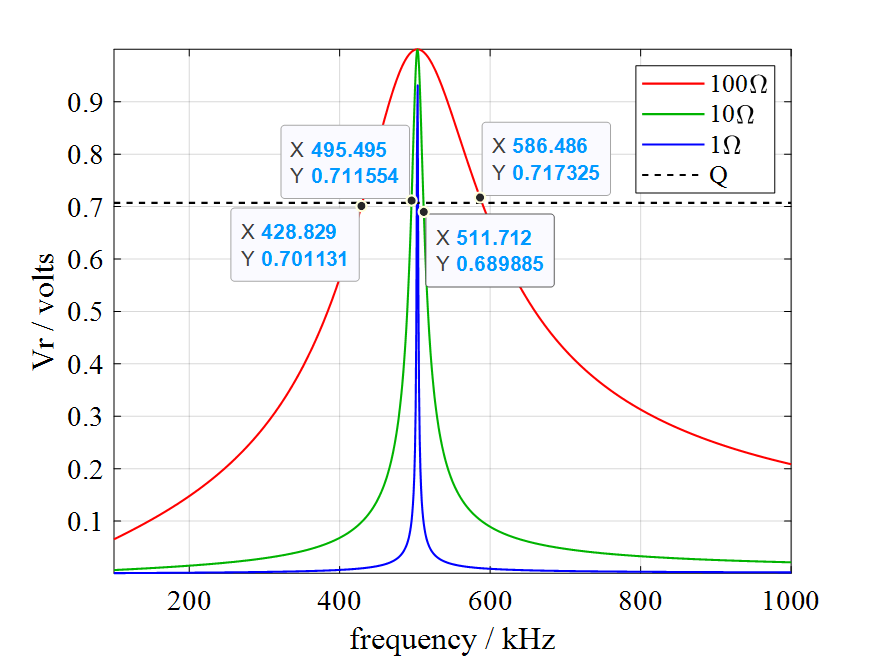

Full width at 1/2 power ~ 586-428kHz = 158kHz, close to 159kHz computed for the red curve. Likewise for the green curve, 511kHz-495kHz = 16kHz vs. 15.9kHz computed above, and the blue curve is presumably 1.59kHz wide at .707 amplitude. A common error is to measure full width at half height (FWHH) at 50% of the peak voltage, instead of 50% of the peak power, which occurs at 70.7% of the peak voltage. It gets a little less confusing when working at radio frequencies (RF), where voltages (and currents) are difficult to measure and power is the primary quantity one deals with. 

## parallel LC

For L and C in parallel, and in series with R:

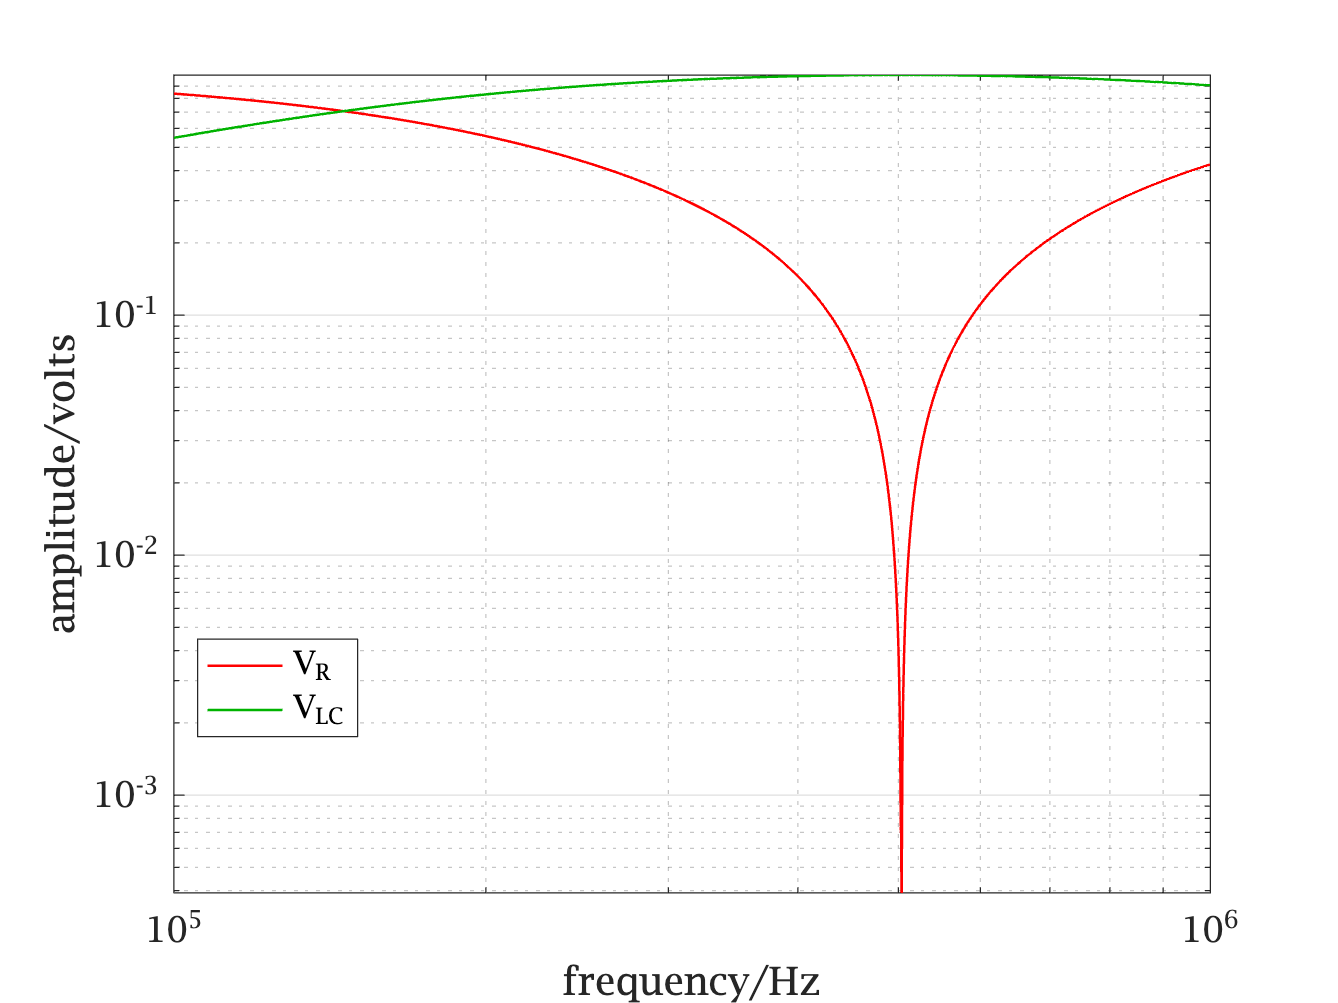

xp = zp(xc, xl);
Ztot = R+xp;
Vr = Vin * R ./ Ztot;
Vlc = Vin * xp ./ Ztot;
loglog(freqs, abs([Vr Vlc])/Vin); 
legend('V_R','V_L_C','location','best'); 
grid; axis tight;
xlabel('frequency/Hz'); 
ylabel('amplitude/volts');

Parallel LC makes a "notch" filter with strong *attenuation* at the resonance. This is handy to remove an unwanted frequency (like a PWM frequency -- although multiple notches will be needed for each significant PWM harmonic -- unless one uses a low pass (1st or 2nd order like we did) that kills the higher harmonics while the notch gives extra attenuation at the strongest fundamental ... choices, choices. See if you can find reasonable values of L, C, R to make a practical notch filter at 980Hz. 

## Building a RLC circuit

We don't have the component values in this modeled circuit, nor can we measure AC waveforms and phases at a resonant frequency that is nearly a decade (10x) above our Nyquist frequency, $f_N$ = sample rate / 2 ~ 2.2kHz. What inductors do we have in the kit? There is a relay. I found a datasheet for it at Mouser.com (searching for "Songle", the manufacturer printed on the relay ([https://www.mouser.com/datasheet/2/272/SRD_05VDC_SL_C-2489437.pdf](https://www.mouser.com/datasheet/2/272/SRD_05VDC_SL_C-2489437.pdf)). It doesn't specifiy the inductance (since relays aren't generally used as inductors), but we can estimate it from two parameters in the datasheet: the coil resistance = 70 ohms +-10% (and you should verify that with your ohmmeter -- which also verifies which pins connect to the coil -- mine measured 68 ohms); and the "operation time" and "release time", <~5-10msec, which are determined by both the electrical inertia (inductance) and mechanical inertia. An upper limit for the inductance is $L \approx R_{coil} * \tau$ 

L = 70*5e-3, % henries 

L = 0.3500

What resonant frequencies can we expect with our kit capacitors? Consider that a polarized electrolytic capacitor has much lower C than its rating when reverse polarized, so they aren't a good choice. That leaves 

C = [100e-12 .1e-6];
f0 = 1 ./ (2*pi*sqrt(L*C))

f0 = 1.0e+04 *

    2.6902    0.0851


With a 100nF = 0.1uf capacitor in series, we expect a measurable resonant frequency of 850Hz. The other key parameter of resonance is the width of the curve, typically described by $Q = \frac{1}{R}\sqrt\frac{L}{C} = \frac{R}{\omega_0 L} = \frac{1}{\omega_0 RC}$ where $\omega_0 = 2\pi*850Hz$. Our smallest R = 100 ohms, but that might be a heavy load on the function generator when the (complex) impedances of C and L cancel each other, so let's explore 1kohm (and we should add $R_{coil}$ to it since they are in series): 

 C = C(2); f0 = f0(2); % picking one
 Q = 1/(1e3+70) * sqrt(L/C)

Q = 1.7484

The bandwidth of the resonance is given by Fo / Q: 

 bandwidth = f0 / Q

bandwidth = 486.5594

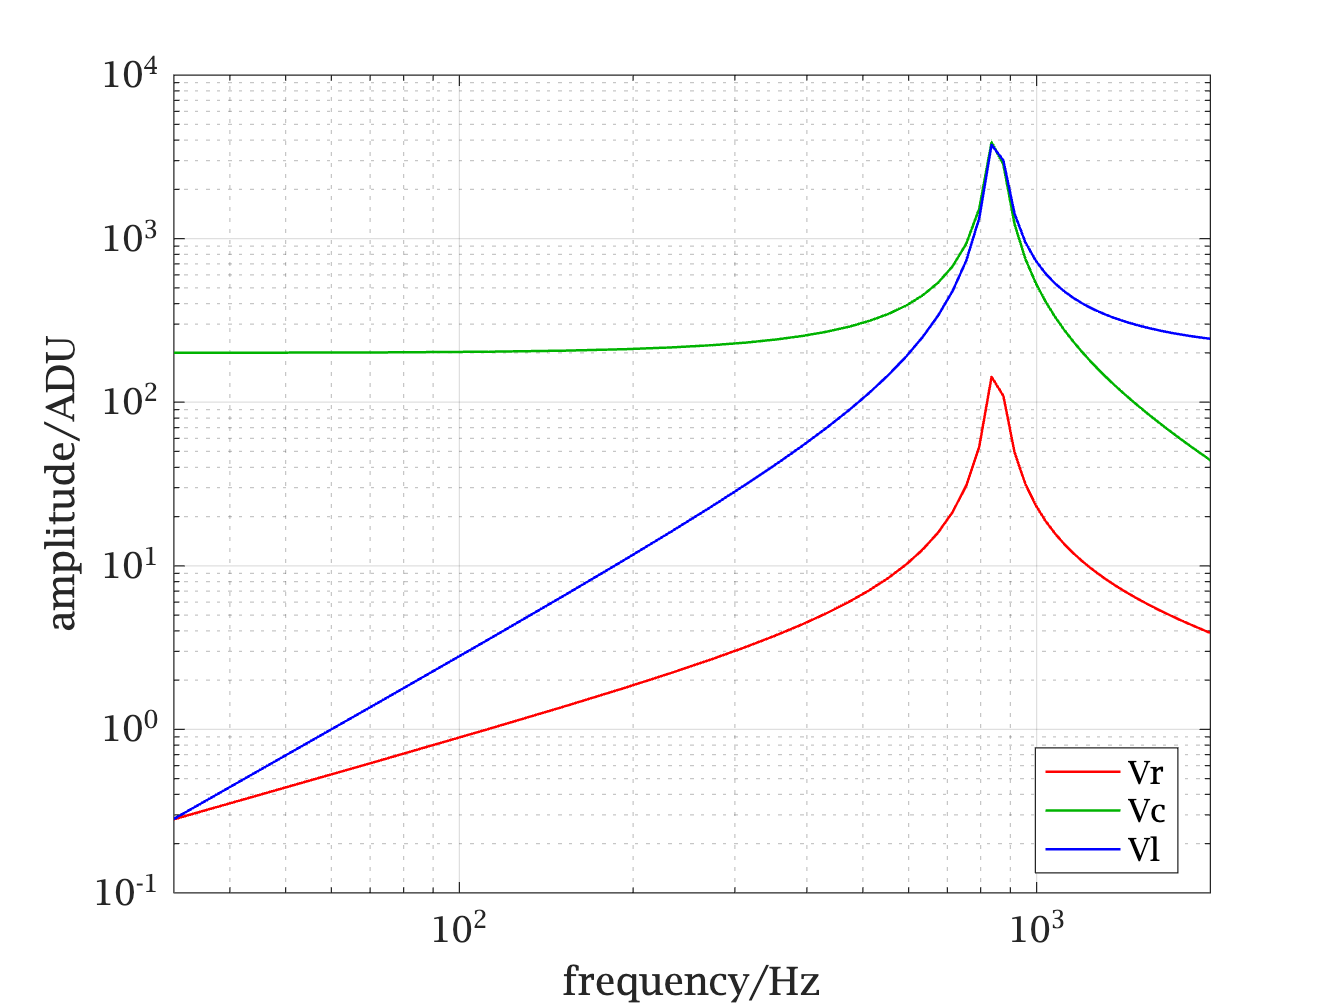

 % let's model this circuit
setFreqs = linspace(32,2000,50)';
Vin = 200; % ADU
R = 70; 
xc = zc(C,setFreqs);
xl = zl(L, setFreqs);
Ztot = R + xc + xl;
Vr = Vin * R ./ Ztot; 
Vc = Vin * xc ./ Ztot;
Vl = Vin * xl ./ Ztot;

loglog(setFreqs, abs([Vr Vc Vl]))
legend('Vr','Vc','Vl','location','best')
grid;
xlabel('frequency/Hz'); 
ylabel('amplitude/ADU');

That should be measurable with our kit (don't try to measure Vl or Vc, as they exceed 3000ADU!). On the other hand this is using an upper bound for L. If L were 10x smaller (which is probable): 

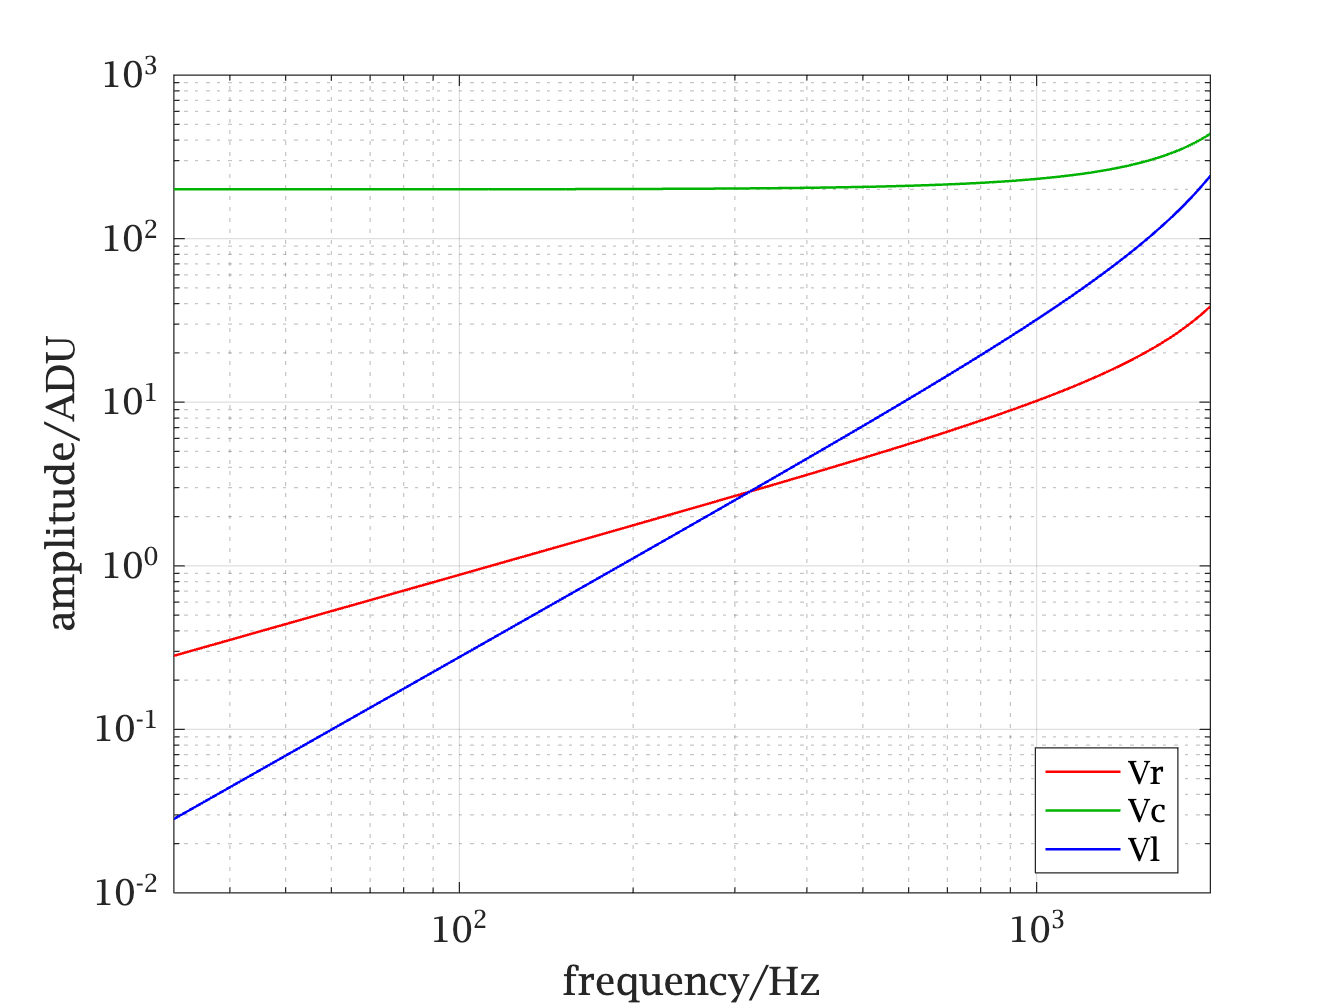

xl = zl(L/10, setFreqs);
Ztot = R + xc + xl;
Vr = Vin * R ./ Ztot; 
Vc = Vin * xc ./ Ztot;
Vl = Vin * xl ./ Ztot;

loglog(setFreqs, abs([Vr Vc Vl]))
legend('Vr','Vc','Vl','location','best')
grid;
xlabel('frequency/Hz'); 
ylabel('amplitude/ADU');

Then the resonance falls is above Arduino's Nyquist frequency.

## Going deeper 

Q plays a key role in many devices and applications. A high Q lets you *select* one frequency band and reject adjacent ones. This lets a radio tune one station and ignore signals on adjacent ones, e.g., Fig. 7.40. The Federal Communication Commission (FCC) is an important branch of government regulating radio emissions in the USA that gives (or sells) licenses in different locations so radio, television, cell phone, wireless data, military, etc. can coexist with minimal interference from each other. Every major country has an equivalent agency. This is an important government service, which we'll likely see weakened by the incoming administration. Elon Musk's Starlink satelites for example, have violated FCC rules by radiating in forbidden bands reserved for astronomers. He doesn't give a damn.

Resonant circuits are key to detecting extremely weak signals. Whispering gallery resonators or optical ring resonators ([https://en.wikipedia.org/wiki/Optical_ring_resonators](https://en.wikipedia.org/wiki/Optical_ring_resonators)) exhibit some of the highest Q ~ 35 million ([https://www.researchgate.net/publication/271589311_Large-area_high-Q_SOI_ring_resonators](https://www.researchgate.net/publication/271589311_Large-area_high-Q_SOI_ring_resonators)). Biochemical applications with them have demonstrated sensitivity to individual molecular binding events. How? The index of refraction is ever so slightly altered by a nearby bound molecule. As coherent light passes the molecule Q times, that tiny effect becomes measurable. 

Atomic nuclei with an odd number of neutrons or protons have nuclear magnetic moments that rotate in strong magnetic fields. Nuclear magnetic resonances can be measured with high enough Q's to identify nearby electronic structures of molecules and molecular groups ([https://en.wikipedia.org/wiki/Nuclear_magnetic_resonance_spectroscopy](https://en.wikipedia.org/wiki/Nuclear_magnetic_resonance_spectroscopy)), making this one of the most powerful techniques for analytical chemistry. 

Adding a nonlinear element (e.g., a diode) to a resonant circuit can lead to chaos -- a deterministic circuit who's output is so sensitive to initial input that its behavior is practically unpredictable and random, e.g., [https://neurophysics.ucsd.edu/courses/physics_173_273/Chaotic_Circuit_03.pdf](https://neurophysics.ucsd.edu/courses/physics_173_273/Chaotic_Circuit_03.pdf)  and [https://www.instructables.com/A-Simple-Chaos-Generator/.](https://www.instructables.com/A-Simple-Chaos-Generator) These circuits are perhaps the easiest apparatus one can build that exhibit some of these "universal" transitions to chaos ([https://en.wikipedia.org/wiki/Universality_(dynamical_systems)](https://en.wikipedia.org/wiki/Universality_(dynamical_systems))). 

Where else do you find resonances, $f_r$'s, and Q's in your world? 

Here's a fun activity involving an Arduino and resonance: –[https://www.instructables.com/IKEA-Frame-Hack-SLOMO-Slow-Motion-Frame/](https://www.instructables.com/IKEA-Frame-Hack-SLOMO-Slow-Motion-Frame/) 

Resonances are what amplify small vibrations in most musical instruments, e.g., [https://youtu.be/gDm4IphrlYg](https://youtu.be/gDm4IphrlYg) 